clear;
file = 'emailSample1.txt';
contents = fileread(file);

processed = string(contents);
processed  = lower(processed);
processed  = eraseBetween(processed,'<','>','Boundaries','inclusive');
processed = replace(processed,"$","dollar");
processed = split(processed);
processed(startsWith(processed,["http://","https://"])) =  "httpaddr";
processed = regexprep(processed,'.+@.+',"emailaddr"); 
processed = regexprep(processed,'[0-9]+',"number");
processed = regexprep(processed,'[^a-zA-Z0-9]',"");
processed(strlength(processed)<=1) = [];

processed = arrayfun(@(str)string(porterStemmer(char(str))),processed)

processed = 58×1 string array
    "anyon"
    "know"
    "how"
    "much"
    "it"
    "cost"
    "to"
    "host"
    "web"
    "portal"
    "well"
    "it"
    "depend"
    "on"
    "how"
    "mani"
    "visitor"
    "your"
    "expect"
    "thi"
    "can"
    "be"
    "anywher"
    "from"
    "less"
    "than"
    "number"
    "buck"
    "month"
    "to"




vocab = readtable('vocab.txt');
vocab = string(vocab{:,2}); 

x=ismember(vocab,processed)

x = 1899×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


features = double(x);
   
table(vocab,features)

ans = 1899×2 table
      vocab      features
    _________    ________

    "aa"            0    
    "ab"            0    
    "abil"          0    
    "abl"           0    
    "about"         0    
    "abov"          0    
    "absolut"       0    
    "abus"          0    
    "ac"            0    
    "accept"        0    
    "access"        0    
    "accord"        0    
    "account"       0    
    "achiev"        0    
    "acquir"        0    
    "across"        0    


|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |    0.038333 |     0.49965 |    0.038333 |    0.038333 |   0.00016516 |


|    2 | Accept |      0.0575 |     0.70774 |    0.038333 |    0.040007 |      0.83735 |


|    3 | Best   |      0.0375 |     0.93903 |      0.0375 |    0.037501 |   8.3856e-07 |


|    4 | Best   |    0.036667 |      0.5437 |    0.036667 |    0.036668 |   1.5247e-08 |


|    5 | Accept |    0.036667 |     0.60461 |    0.036667 |    0.036666 |   2.5029e-09 |


|    6 | Accept |      0.0375 |     0.35853 |    0.036667 |    0.036664 |   1.4217e-05 |


|    7 | Best   |       0.035 |     0.47075 |       0.035 |    0.036096 |   6.0521e-09 |


|    8 | Accept |    0.035833 |     0.37866 |       0.035 |    0.036023 |   2.5058e-09 |


|    9 | Accept |    0.038333 |     0.31922 |       0.035 |     0.03641 |   2.5027e-09 |


|   10 | Accept |    0.036667 |      0.3205 |       0.035 |    0.036452 |   3.0313e-08 |


|   11 | Accept |    0.036667 |      0.4447 |       0.035 |    0.036476 |   1.9813e-08 |


|   12 | Accept |     0.31917 |     0.32855 |       0.035 |    0.035306 |       24.955 |


|   13 | Best   |      0.0225 |     0.36211 |      0.0225 |    0.022462 |     0.028971 |


|   14 | Accept |    0.029167 |     0.45992 |      0.0225 |    0.022583 |      0.11581 |


|   15 | Accept |    0.025833 |     0.40289 |      0.0225 |    0.022661 |    0.0040394 |


|   16 | Best   |    0.021667 |     0.43231 |    0.021667 |     0.02172 |       0.0136 |


|   17 | Best   |        0.02 |     0.47944 |        0.02 |    0.020975 |     0.014908 |


|   18 | Best   |    0.019167 |     0.41397 |    0.019167 |    0.020442 |     0.014188 |


|   19 | Accept |    0.021667 |       0.532 |    0.019167 |    0.020723 |     0.013466 |


|   20 | Accept |       0.035 |      0.6954 |    0.019167 |    0.020741 |   0.00079265 |


|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|   21 | Accept |      0.0375 |     0.63061 |    0.019167 |    0.020757 |   3.3681e-06 |


|   22 | Accept |      0.0375 |     0.38977 |    0.019167 |    0.020768 |   1.8635e-07 |


|   23 | Accept |      0.0375 |     0.40741 |    0.019167 |    0.020773 |   4.9171e-05 |


|   24 | Accept |      0.3125 |      1.5876 |    0.019167 |    0.020087 |       3.8659 |


|   25 | Accept |    0.040833 |     0.51259 |    0.019167 |    0.020517 |      0.33251 |


|   26 | Accept |    0.030833 |     0.40004 |    0.019167 |    0.020534 |    0.0019547 |


|   27 | Accept |      0.0225 |     0.55396 |    0.019167 |    0.020559 |     0.058404 |


|   28 | Best   |      0.0175 |     0.38762 |      0.0175 |     0.01805 |     0.018635 |


|   29 | Best   |    0.016667 |       0.402 |    0.016667 |    0.017395 |     0.019003 |


|   30 | Accept |    0.018333 |     0.51396 |    0.016667 |    0.017685 |       0.0192 |


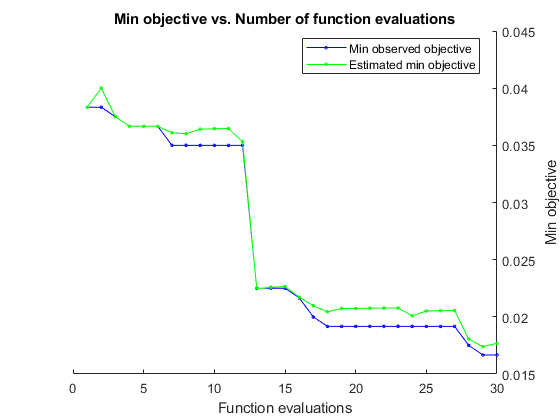

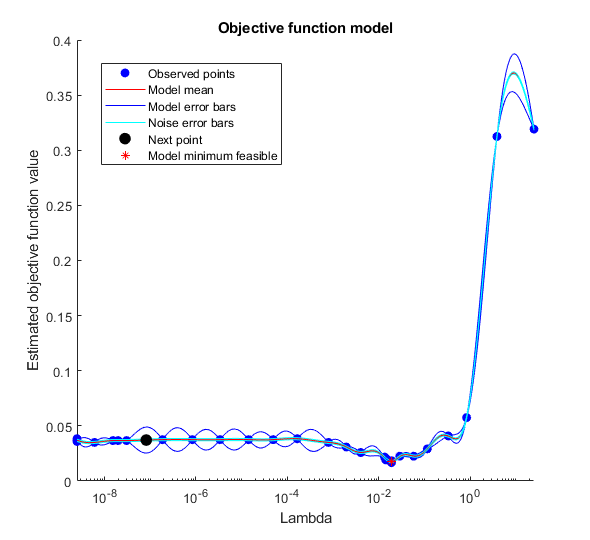


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 72.1429 seconds.
Total objective function evaluation time: 15.4792

Best observed feasible point:
          Lambda      
    __________________

    0.0190031360440149

Observed objective function value = 0.016667
Estimated objective function value = 0.017685
Function evaluation time = 0.402

Best estimated feasible point (according to models):
         Lambda      
    _________________

    0.018635429927768

Estimated objective function value = 0.017685
Estimated function evaluation time = 0.48257



linSVMmdl =   ClassificationLinear
      ResponseName: 'Y'
        ClassNames: [0 1]
    ScoreTransform: 'none'
              Beta: [1899×1 double]
              Bias: -0.067968461076583
            Lambda: 0.018635429927768
           Learner: 'svm'


  Properties, Methods




load spamTrain.mat;
opts = struct('Holdout',0.3);
linSVMmdl = fitclinear(X,y,'Learner','svm','Regularization','ridge','OptimizeHyperparameters',{'lambda'},'HyperparameterOptimizationOptions',opts)

load('spamTest.mat');
fprintf('Training Accuracy: %f | Test Accuracy: %f\n',...
        mean(predict(linSVMmdl,X)==y)*100,...
        mean(predict(linSVMmdl,Xtest)==ytest)*100);

Training Accuracy: 98.775000 | Test Accuracy: 98.500000


    
    
yourEmail = 'testemailfromdeepai.txt';
eml = yourEmail;
processed = preprocess(eml);
features = ismember(vocab,processed);
if predict(linSVMmdl,double(features)')
    disp('This email is probably spam.')
else
    disp('This email is probably not spam.')
end

This email is probably not spam.


%preprocess function

function contents = preprocess(file)
    contents = string(fileread(file));
    contents  = lower(contents);
    contents  = eraseBetween(contents,'<','>','Boundaries','inclusive');
    contents = replace(contents,"$","dollar ");
    contents = split(contents);
    contents(startsWith(contents,["http://","https://"])) =  "httpaddr";
    contents = regexprep(contents,'.+@.+',"emailaddr"); 
    contents = regexprep(contents,'[0-9]+',"number");
    contents = regexprep(contents,'[^a-zA-Z0-9]',"");
    contents(strlength(contents)<=1) = [];
    contents = arrayfun(@(str)string(porterStemmer(char(str))),contents);
end


